## NUMERICAL EXAMPLES

### ESTIMATING THE BUILDING HEIGHT

Assume that we would like to estimate the height of the building using very imprecise altimeter.

We know for sure, that the building height doesn’t change over time, at least during the short measurement process.

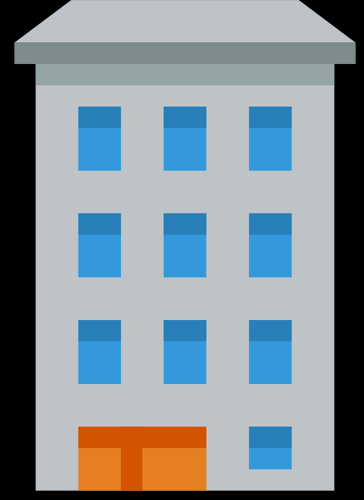

- The true building height is 50 meters.

- The altimeter measurement error (standard deviation) is 5 meters.

- The set of ten measurements is: 48.54m, 47.11m, 55.01m, 55.15m, 49.89m, 40.85m, 46.72m, 50.05m, 51.27m, 49.95m.

clc;
clear;
measurements = [48.54 47.11 55.01 55.15 49.89 40.85 46.72 50.05 51.27 49.95]; %meter

**INITIALIZATION**

One can estimate the building height simply by looking on it.

The estimated building height is:

estimatedHeight = 60; %meter, estimated by a human

Now we shall initialize the estimate uncertainty. Human’s estimation error (standard deviation) is about 15 meters: σ=15 . Consequently the variance is 225: σ2=225 .

estimatedUncertainty = 225; %p_{i}_{i}

**PREDICTION**

Now, we shall predict the next state based on the initialization values.

Since the using system’s Dynamic Model is constant, i.e. the building doesn’t change its height, then:

predictedHeight = estimatedHeight; %meter

The extrapolated estimate uncertainty (variance) also doesn’t change:

extrapolatedEstimateUncertainty = estimatedUncertainty; %p_{i+1}_{i} Like prediction of uncertainty

**ITERATION**

kalmanGainValues = [];
estimatedHeightValues = [];
estimatedUncertaintyValues = [];
predictedHeightValues = [];
extrapolatedEstimateUncertaintyValues = [];

for i=1:10
    %Measure
    z = measurements(i);
    rMeasurement = 5^2; %the standard deviation (σ) of the altimeter measurement error is 5, the variance (σ^2) would be 25, thus the measurement uncertainty is: r1=25.
    
    %Update-Estimate
    kalmanGain = extrapolatedEstimateUncertainty/(extrapolatedEstimateUncertainty+rMeasurement);    
    estimatedHeight = predictedHeight + kalmanGain*(z-predictedHeight);
    estimatedUncertainty = (1-kalmanGain)*extrapolatedEstimateUncertainty;
    kalmanGainValues(i) = kalmanGain;
    estimatedHeightValues(i) = estimatedHeight;
    estimatedUncertaintyValues(i) = estimatedUncertainty;
    
    %Prediction
    predictedHeight = estimatedHeight;
    extrapolatedEstimateUncertainty = estimatedUncertainty;
    predictedHeightValues(i)=predictedHeight;
    extrapolatedEstimateUncertaintyValues(i)=extrapolatedEstimateUncertainty;
end

Let's figure the height values;

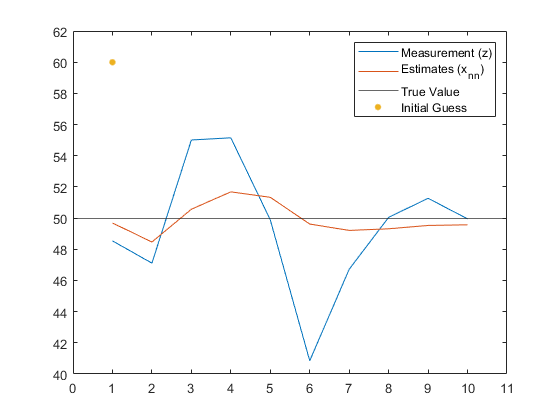

figure();
plot(measurements,"DisplayName","Measurement (z)");
hold on;
plot(estimatedHeightValues,"DisplayName","Estimates (x_n_n)");
hold on;
yline(50,"DisplayName","True Value");
hold on;
plot(1,60,'.',"MarkerSize", 15, "DisplayName","Initial Guess");
hold off;
ylim([40 62]);
xlim([0 11]);
legend;

As you can see the estimated value converges about 49.5 meters after 7 measurements.

Let's figure the uncertainty values;

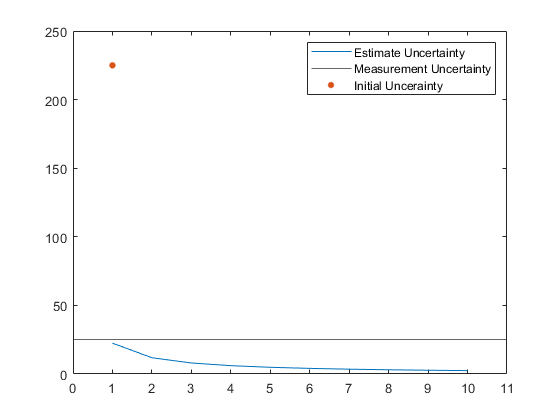

figure();
plot(estimatedUncertaintyValues,"DisplayName","Estimate Uncertainty");
hold on;
yline(25,"DisplayName","Measurement Uncertainty");
hold on;
plot(1,225,'.',"MarkerSize", 15, "DisplayName","Initial Uncerainty");
hold off;
xlim([0 11]);
legend;

At the first filter iteration, the estimate uncertainty is close to the measurement uncertainty, and it quickly goes down. After 10 measurements the estimate uncertainty ( σ^2 ) is 2.47, i.e. the estimate error standard deviation is: σ=√2.47=1.57m

So we can say that the building height estimate is: 49.57±1.57m

Let's show Kalman gain graph;

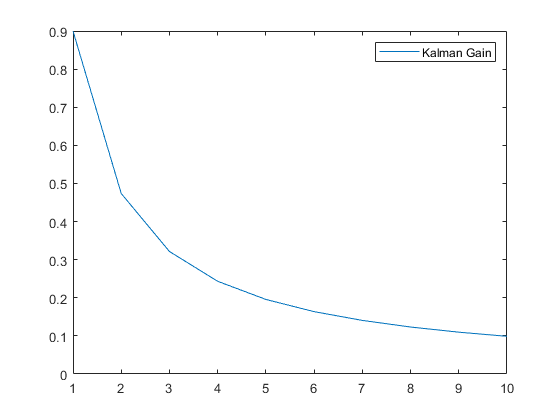

figure();
plot(kalmanGainValues,"DisplayName","Kalman Gain");
legend;

As you can see, the Kalman Gain is going down, making the measurement weight smaller and smaller.

### ESTIMATING THE TEMPERATURE OF THE LIQUID IN A TANK

In the previous example we've estimated the building height. The building height doesn't change. Therefore, we didn't take the process noise into consideration.

The **Process Noise Variance** is denoted by letter q.

The **Covariance Extrapolation Equation** shall include the **Process Noise Variance**.

The Covariance Extrapolation Equation for constant dynamics is:


$$p_{n+1,n} = p_{n,n}+q_{n}$$


We would like to estimate the temperature of the liquid in a tank.

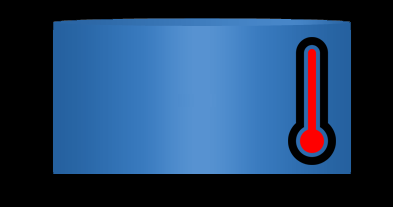

We assume that at the steady state the liquid temperature is constant. However, some fluctuations in the true liquid temperature are possible. We can describe the system dynamics by the following equation:


$$x_n=T+w_n$$


where:

$T$ is the constant temperature

$w_n$ is a random process noise with variance $q$.

**NUMERICAL EXAMPLE**

- Let us assume the true temperature of 50 degrees Celsius.

- We think that we have an accurate model, thus we set the process noise variance (q) to 0.0001.

- The measurement error (standard deviation) is 0.1 degrees Celsius.

- The measurements are taken every 5 seconds.

- The true liquid temperature at the measurement points is: 49.979, 50.025, 50, 50.003, 49.994, 50.002, 49.999, 50.006, 49.998, and 49.991.

- The set of measurements is: 49.9, 49.967, 50.1, 50.106, 49.992, 49.819, 49.933, 50.007, 50.023, and 49.99.

The following chart compares the true liquid temperature and the measurements.

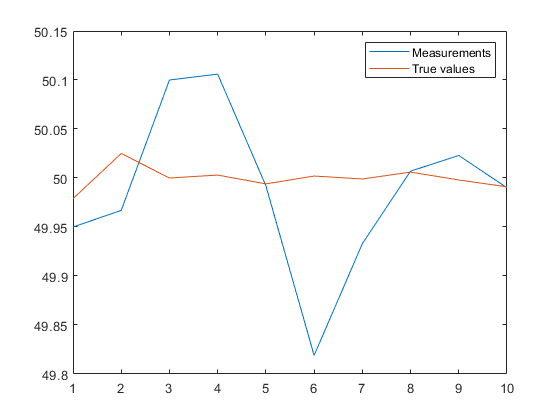

clc;
clear;
measurements = [49.95 49.967 50.1 50.106 49.992 49.819 49.933 50.007 50.023 49.99];
trueValues = [49.979 50.025 50 50.003 49.994 50.002 49.999 50.006 49.998 49.991];

figure();
plot(measurements,"DisplayName","Measurements");
hold on;
plot(trueValues,"DisplayName","True values");
hold off;
legend;

**INITIALIZATION**

**ESTIMATION**

We don't know what the temperature of the liquid is, and our guess is 10.

estimatedTemperature = 10;

Our guess is very imprecise, we set our initialization estimate error σ to 100. The **Estimate Uncertainty** of the initialization is the error variance (σ2):

estimatedUncertainty = 100^2;

This variance is very high. If we initialize with a more meaningful value, we will get faster Kalman Filter convergence.

**PREDICTION**

Now, we shall predict the next state based on the initialization values.

Since our model is constant dynamics, the predicted estimate is equal to the current estimate:

predictedTemperature = estimatedTemperature;

The extrapolated estimate uncertainty (variance):

q = 0.0001;
extrapolatedEstimateUncertainty = estimatedUncertainty + q;

**ITERATION**

estimatedTemperatureValues = [];
predictedTemperatureValues = [];
kalmanGainValues = [];
estimatedUncertaintyValues = [];
extrapolatedEstimateUncertaintyValues = [];
for i=1:10
    %Measure
    z = measurements(i);
    rMeasurement = 0.1^2; %Measurement uncertainty
    
    %Update-Estimate
    kalmanGain = extrapolatedEstimateUncertainty/(extrapolatedEstimateUncertainty+rMeasurement);
    estimatedTemperature = predictedTemperature + kalmanGain*(z-predictedTemperature);
    estimatedUncertainty = (1-kalmanGain)*extrapolatedEstimateUncertainty;
    estimatedTemperatureValues(i)=estimatedTemperature;
    estimatedUncertaintyValues(i)=estimatedUncertainty;
    kalmanGainValues(i)=kalmanGain;
    
    %Prediction
    predictedTemperature = estimatedTemperature;
    extrapolatedEstimateUncertainty = estimatedUncertainty+q;
    predictedTemperatureValues(i)=predictedTemperature;
    extrapolatedEstimateUncertaintyValues(i)=extrapolatedEstimateUncertainty;
end

Let's figure the temperature values;

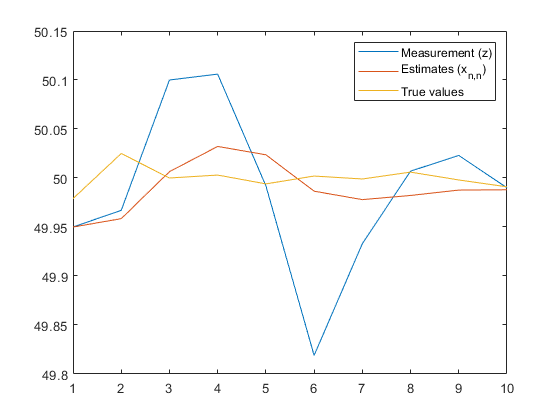

figure();
plot(measurements,"DisplayName","Measurement (z)");
hold on;
plot(estimatedTemperatureValues,"DisplayName","Estimates (x_{n,n})");
hold on;
plot(trueValues,"DisplayName","True values");
hold off;
legend;

As you can see the estimated value converges towards the true value.

The next chart shows the estimate uncertainty.

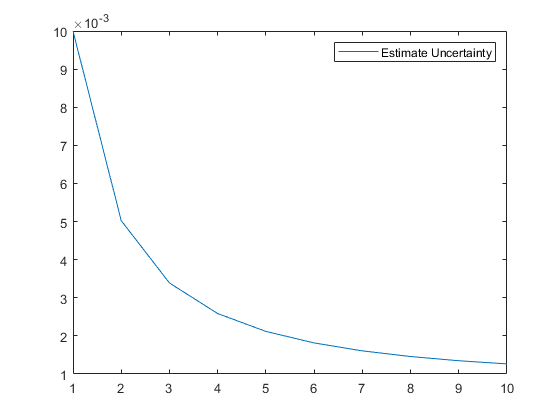

figure();
plot(estimatedUncertaintyValues,"DisplayName","Estimate Uncertainty");
hold on;
legend;

The estimate uncertainty quickly goes down. After 10 measurements, the estimate uncertainty ( σ^2 ) is 0.0013, i.e. the estimate error standard deviation is: σ=√0.0013=0.036.

So we can say that the liquid temperature estimate is: 49.988±0.036 in celcius.

The next chart shows the Kalman Gain.

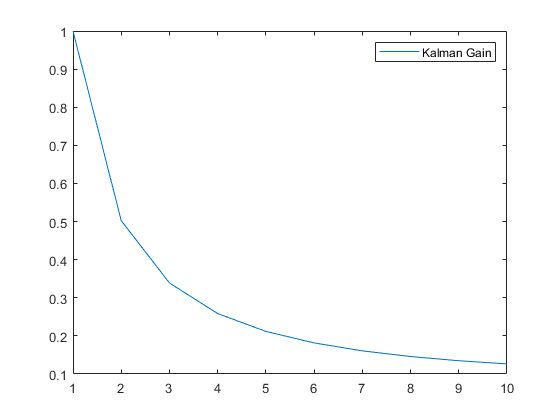

figure();
plot(kalmanGainValues,"DisplayName","Kalman Gain");
legend;

As you can see, the Kalman Gain is going down, making the measurement weight smaller and smaller.

In this example we've measured the liquid temperature using the one-dimensional Kalman Filter. Although the system dynamics including a random process noise, the Kalman Filter can provide good estimation.

### ESTIMATING THE TEMPERATURE OF THE HEATING LIQUID Ⅰ

Like in the previous example, in this example we are going to estimate the temperature of the liquid in the tank. The system dynamics is not constant, the liquid is heating at the rate of 0.1 celcius every second.

The Kalman Filter parameters are similar to the previous example:

- We think that we have an accurate model, thus we set the process noise variance (q) to 0.0001.

- The measurement error (standard deviation) is 0.1 celcius.

- The measurements are taken every 5 seconds.

- The system dynamics is constant.

Pay attention, although the real system dynamics is not constant (since the liquid is heating), we are going to treat the system as a system with constant dynamics (the temperature doesn't change).

- The true liquid temperature at the measurement points is: 50.479, 51.025, 51.5, 52.003, 52.494, 53.002, 53.499, 54.006, 54.498, and 54.991 in celcius.

- The set of measurements is: 50.45, 50.967, 51.6, 52.106, 52.492, 52.819, 53.433, 54.007, 54.523, and 54.99 in celcius.

The following chart compares the true liquid temperature and the measurements.

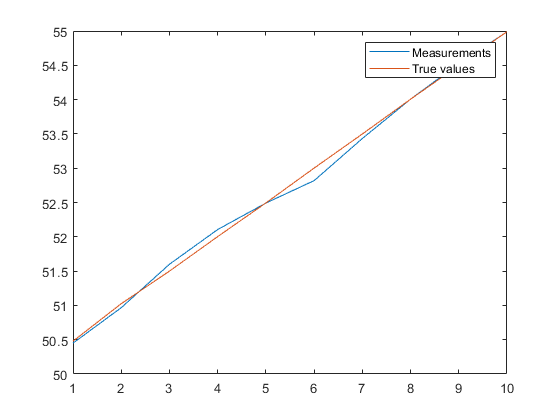

clc;
clear;
trueValues = [50.479 51.025 51.5 52.003 52.494 53.002 53.499 54.006 54.498 54.991];
measurements = [50.45 50.967 51.6 52.106 52.492 52.819 53.433 54.007 54.523 54.99];

figure();
plot(measurements,"DisplayName","Measurements");
hold on;
plot(trueValues,"DisplayName","True values");
hold off;
legend;

**INITIALIZATION**

**ESTIMATE**

We don't know what is the temperature of the liquid in a tank is and our guess is 10 celcius.

estimatedTemperature = 10;

Our guess is very imprecise, we set our initialization estimate error ( σ ) to 100. The **Estimate Uncertainty** of the initialization is the error variance (σ2):

estimatedUncertainty = 100^2;

This variance is very high. If we initialize with a more meaningful value, we will get faster Kalman Filter convergence.

**PREDICTION**

Now, we shall predict the next state based on the initialization values.

Since our model is constant dynamics, the predicted estimate is equal to the current estimate:

predictedTemperature = estimatedTemperature;

The extrapolated estimate uncertainty (variance):

q=0.0001;
extrapolatedEstimateUncertainty = estimatedUncertainty + q;

**ITERATION**

estimatedTemperatureValues = [];
predictedTemperatureValues = [];
kalmanGainValues = [];
estimatedUncertaintyValues = [];
extrapolatedEstimateUncertaintyValues = [];
for i=1:10
    %Measure
    z = measurements(i);
    rMeasurement = 0.1^2; %Measurement uncertainty
    
    %Update-Estimate
    kalmanGain = extrapolatedEstimateUncertainty/(extrapolatedEstimateUncertainty+rMeasurement);
    estimatedTemperature = predictedTemperature + kalmanGain*(z-predictedTemperature);
    estimatedUncertainty = (1-kalmanGain)*extrapolatedEstimateUncertainty;
    estimatedTemperatureValues(i)=estimatedTemperature;
    estimatedUncertaintyValues(i)=estimatedUncertainty;
    kalmanGainValues(i)=kalmanGain;
    
    %Prediction
    predictedTemperature = estimatedTemperature;
    extrapolatedEstimateUncertainty = estimatedUncertainty+q;
    predictedTemperatureValues(i)=predictedTemperature;
    extrapolatedEstimateUncertaintyValues(i)=extrapolatedEstimateUncertainty;
end

Let's figure the temperature values;

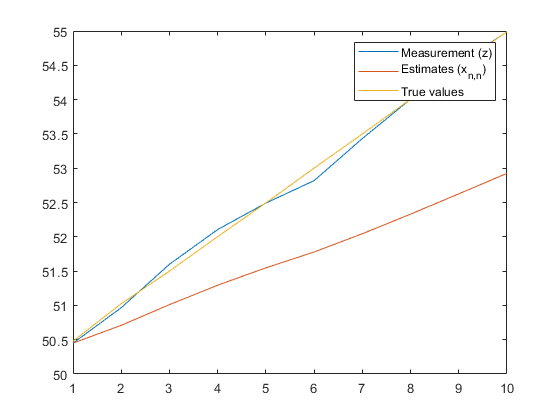

figure();
plot(measurements,"DisplayName","Measurement (z)");
hold on;
plot(estimatedTemperatureValues,"DisplayName","Estimates (x_{n,n})");
hold on;
plot(trueValues,"DisplayName","True values");
hold off;
legend;

As you can see, the Kalman Filter has failed to provide trustworthy estimation. There is a **lag error** in Kalman Filter estimation. We've already encountered the lag error in [Example 3](https://www.kalmanfilter.net/alphabeta.html#ex3), where we estimated position of accelerating aircraft using the α−β filter that assumes constant aircraft velocity. We got rid of the lag error in [Example 4](https://www.kalmanfilter.net/alphabeta.html#ex4), where we replaced the α−β filter by α−β−γ filter that assumes acceleration.

There are two reasons that causing lag error in our Kalman Filter example:

- The dynamic model doesn't fit the case.

- The process model reliability. We have chosen very low process noise (q=0.0001) while the real temperature fluctuations are much bigger.

**Note: The lag error shall be constant, therefore the estimate curve shall have the same slope of the true value curve. The figure above presents only 10 first measurements and it is not enough for convergence. The figure below presents the first 100 measurements with the constant lag error.**

There are two possible ways to fix the lag error:

- If we know that the liquid temperature can change linearly, we can define a new model that takes into account a possible linear change in the liquid temperature. We did it in [Example 4](https://www.kalmanfilter.net/alphabeta.html#ex4). This is a preferred method. However, if the temperature change can't be modeled, this method won't improve the Kalman Filter performance.

- On the other hand, since our model is not well defined, we can adjust the process model reliability by increasing the process noise (q). See the [next example](https://www.kalmanfilter.net/kalman1d.html#ex8) for details.

In this example, we've measured the temperature of heating liquid using the one-dimensional Kalman Filter with constant dynamic model. We've observed the lag error in the Kalman Filter estimation. The lag error is caused by wrong dynamic model definition and wrong process model definition.

The lag error can be fixed by appropriate definition of the dynamic model or process model.

### ESTIMATING THE TEMPERATURE OF THE HEATING LIQUID Ⅱ

This example is similar to the previous example with only one change. Since our process is not well defined, we will increase the process uncertainty (q) from 0.0001 to 0.15.

clc;
clear;
trueValues = [50.479 51.025 51.5 52.003 52.494 53.002 53.499 54.006 54.498 54.991];
measurements = [50.45 50.967 51.6 52.106 52.492 52.819 53.433 54.007 54.523 54.99];

**INITIALIZATION**

**ESTIMATION**

The initialization zero is similar to the previous example.

We don't know what is the temperature of the liquid in a tank is and our guess is 10 celcius.

estimatedTemperature = 10;

Our guess is very imprecise, we set our initialization estimate error (σ) to 100. The **Estimate Uncertainty** of the initialization is the error variance (σ2):

estimatedUncertainty = 100^2;

This variance is very high. If we initialize with a more meaningful value, we will get faster Kalman Filter convergence.

**PREDICTION**

Now, we shall predict the next state based on the initialization values.

Since our model is constant dynamics, the predicted estimate is equal to the current estimate:

predictedTemperature = estimatedTemperature;

The extrapolated estimate uncertainty (variance):

q = 0.15;
extrapolatedEstimateUncertainty = estimatedUncertainty + q;

**ITERATION**

estimatedTemperatureValues = [];
predictedTemperatureValues = [];
kalmanGainValues = [];
estimatedUncertaintyValues = [];
extrapolatedEstimateUncertaintyValues = [];
for i=1:10
    %Measure
    z = measurements(i);
    rMeasurement = 0.1^2; %Measurement uncertainty
    
    %Update-Estimate
    kalmanGain = extrapolatedEstimateUncertainty/(extrapolatedEstimateUncertainty+rMeasurement);
    estimatedTemperature = predictedTemperature + kalmanGain*(z-predictedTemperature);
    estimatedUncertainty = (1-kalmanGain)*extrapolatedEstimateUncertainty;
    estimatedTemperatureValues(i)=estimatedTemperature;
    estimatedUncertaintyValues(i)=estimatedUncertainty;
    kalmanGainValues(i)=kalmanGain;
    
    %Prediction
    predictedTemperature = estimatedTemperature;
    extrapolatedEstimateUncertainty = estimatedUncertainty+q;
    predictedTemperatureValues(i)=predictedTemperature;
    extrapolatedEstimateUncertaintyValues(i)=extrapolatedEstimateUncertainty;
end

Let's figure the temperature values;

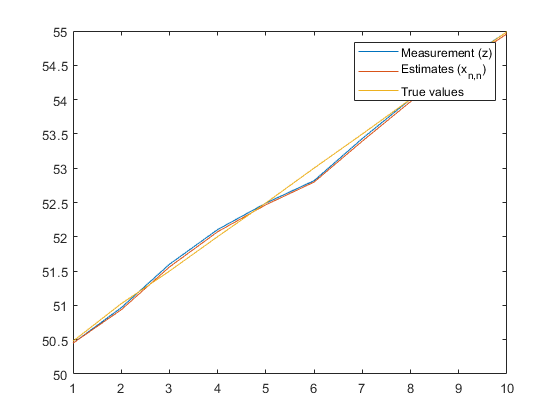

figure();
plot(measurements,"DisplayName","Measurement (z)");
hold on;
plot(estimatedTemperatureValues,"DisplayName","Estimates (x_{n,n})");
hold on;
plot(trueValues,"DisplayName","True values");
hold off;
legend;

The next chart shows the Kalman Gain.

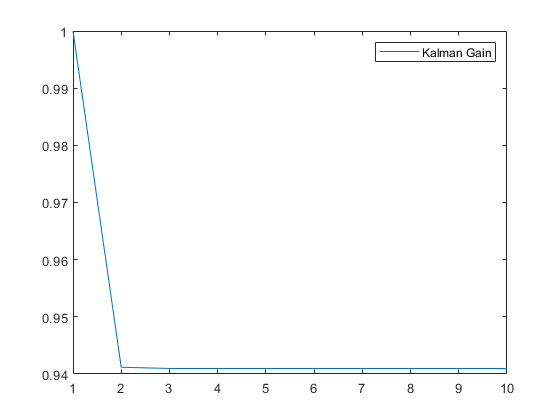

figure();
plot(kalmanGainValues,"DisplayName","Kalman Gain");
legend;

Due to the high process uncertainty, the measurement weight is much higher than the estimate weight, thus the Kalman Gain is high, and it is converged at 0.94.